Problem 1

clear; clc;

(a)


$$L(s) = \frac{100(0.5s+1)}{s(0.2s+1)(s+10)}=\frac{250(s+2)}{s(s+5)(s+10)}$$


Asymptotic approximations of the sketched Bode plot:

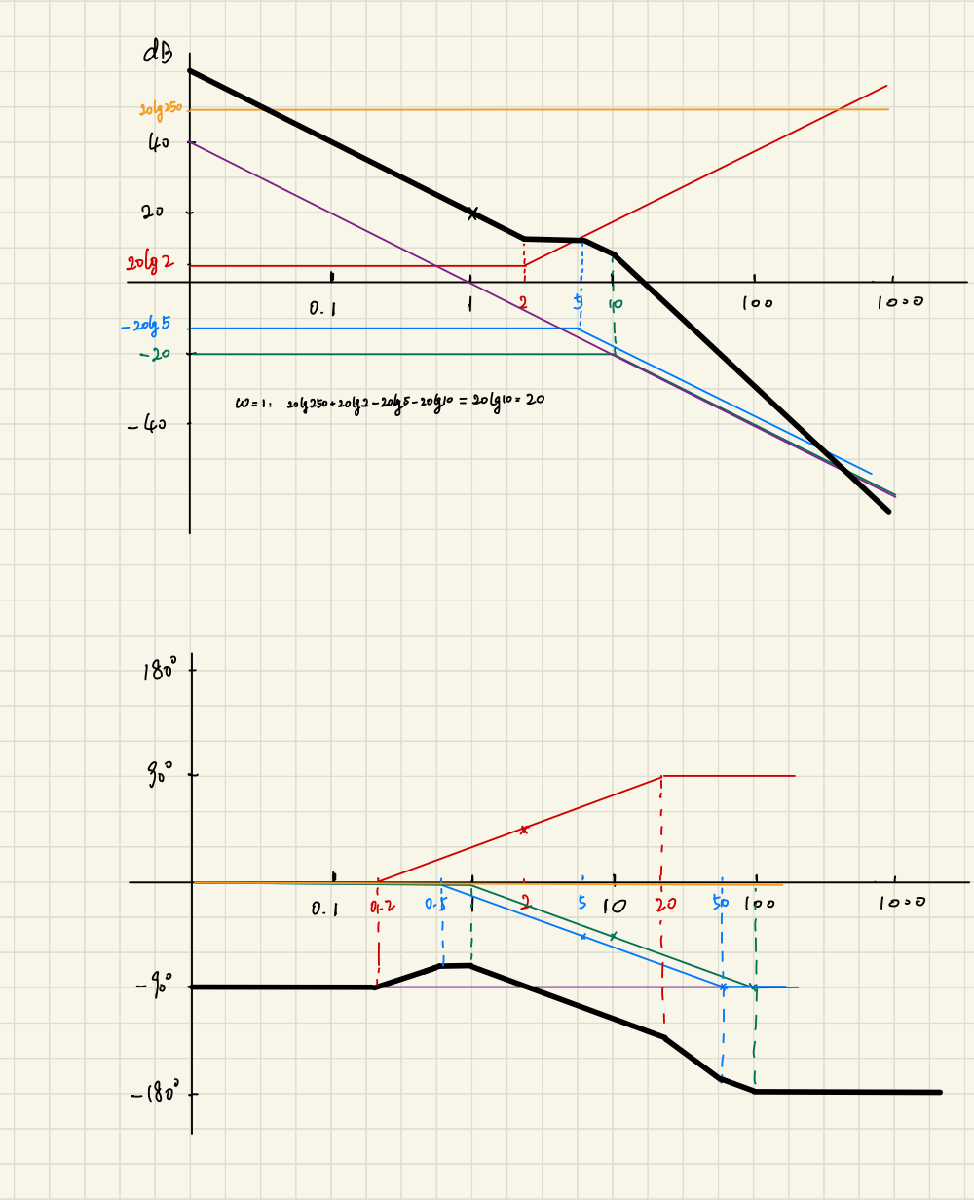

Nyquist plot based on approximate Bode plot:

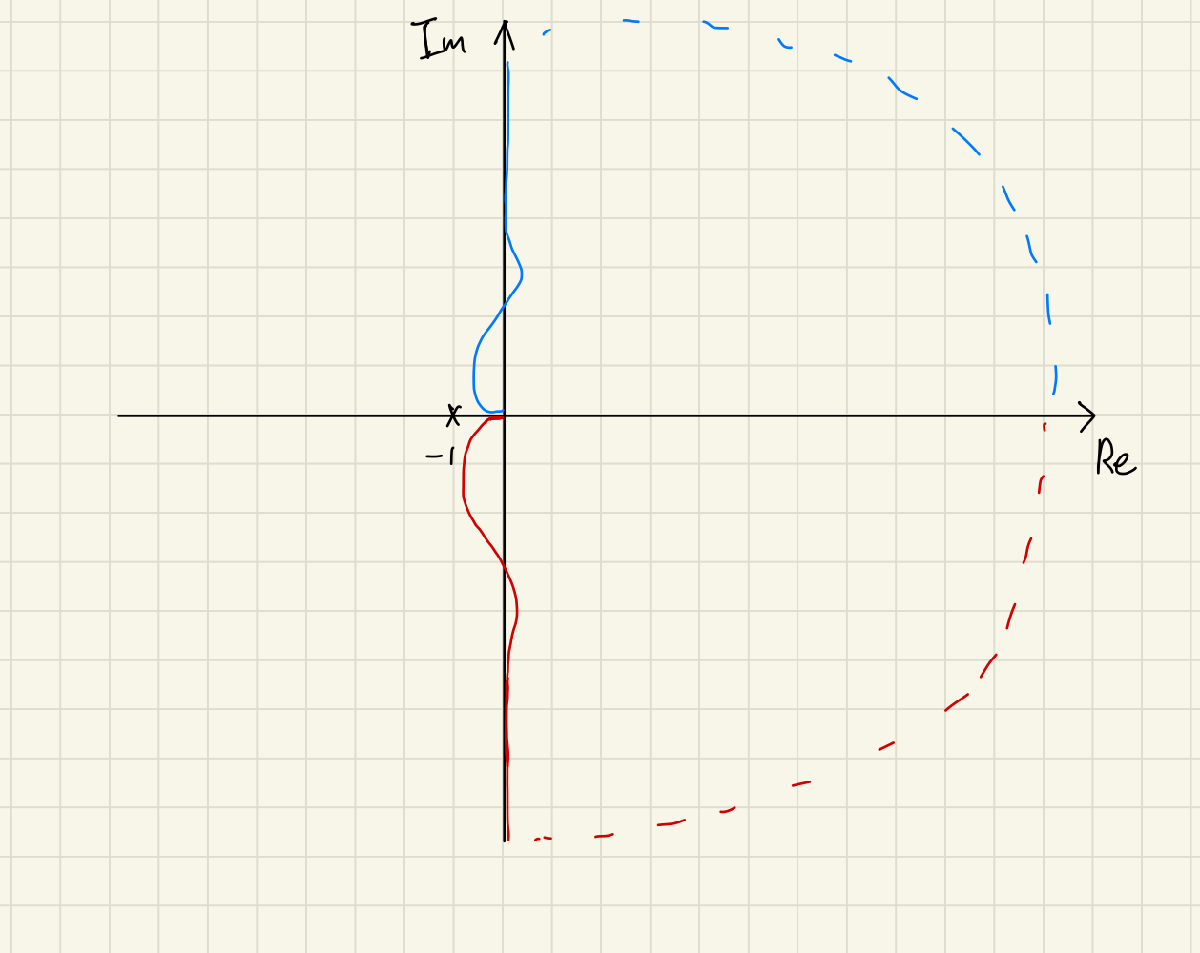

(b)

The gain margin should be the distance to 0dB at the phase crossover frequency. The phase crossover frequency is about 100 rad/s, which corresponds to a gain margin of about 30 dB.

The phase margin should be the distance to -180 deg at the gain crossover frequency. The gain crossover frequency is about 10 rad/s, which corresponds to a phase margin of about 60 deg.

s = tf('s');
L = 250*(s+2)/(s*(s+5)*(s+10));

Make the Bode plot and get margin values.

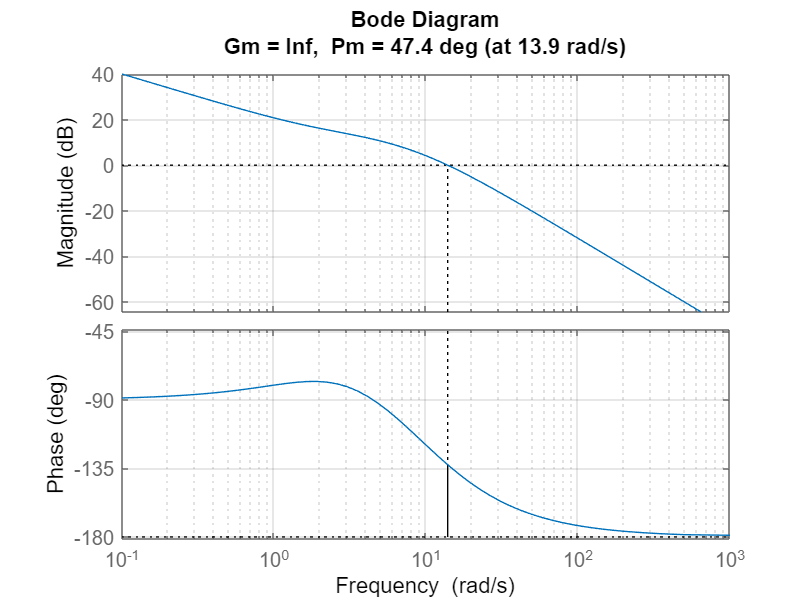

margin(L);
grid on

[GM, PM, w180, wc] = margin(L);

Compare the result based on approximated Bode plot and the exact margin value: Since the accurate Bode plot never reaches -180 deg, the gain margin is then infinity; the gain crossover frequency is 13.9 rad/s, and the phase margin is 47.4 deg, which is slightly smaller than the approximated value.

(c) 

The delay margin is calculated by:


$$T_{max}=\frac{PM}{\omega_c}$$


Tmax = PM/(wc*180/pi)

Tmax = 0.0595

The step response of the closed loop system:

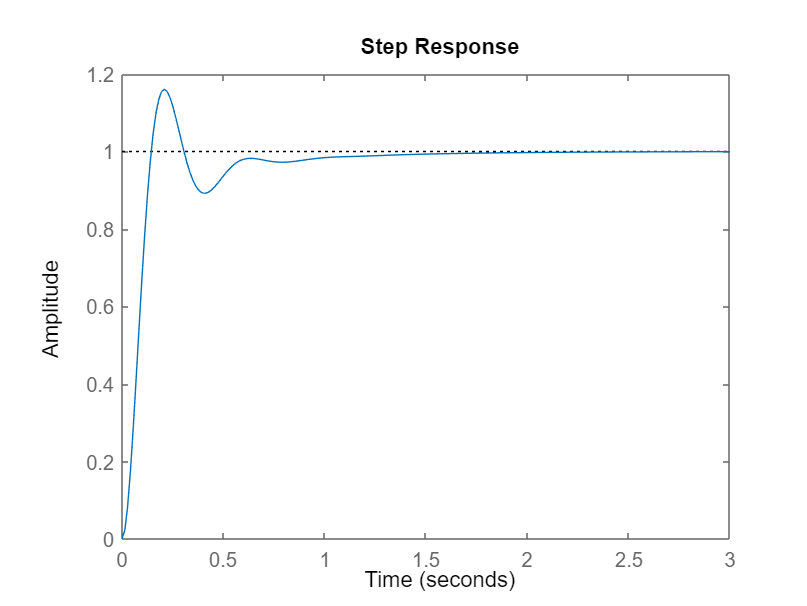

step(feedback(L, 1));

As predicted based on the Nyquist plot, the closed-loop system is stable, since there is no RHP open-loop pole and no clockwise encircle of -1 in the Nyquist plot. 

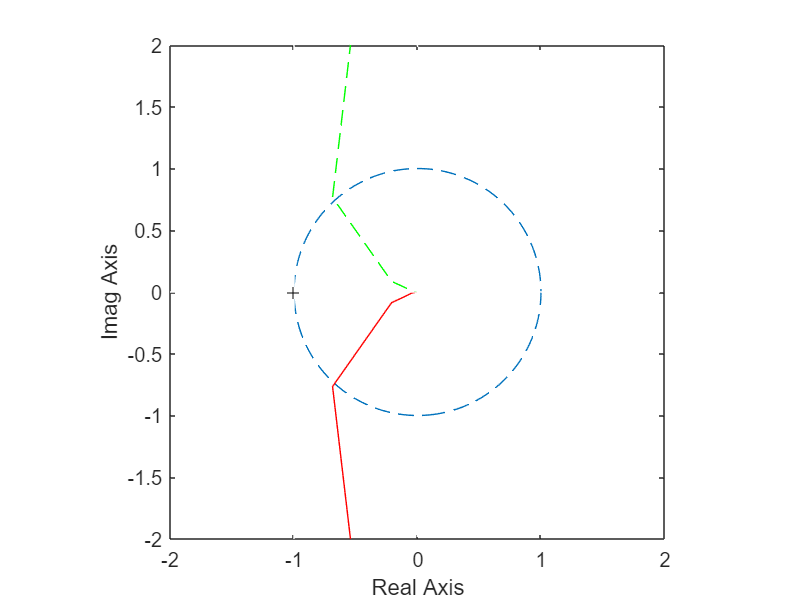

fimplicit(@(x, y)(x.^2+y.^2-1), '--')
axis equal
hold on
nyquist1(L)
hold off
xlim([-2, 2])
ylim([-2, 2])

Problem 2

clear;clc;

(a)


$$G(s)=\frac{100}{s(s+1)(s+10)}$$


s = tf('s');
G = 100/(s*(s+1)*(s+10));

The Bode plot of original plant:

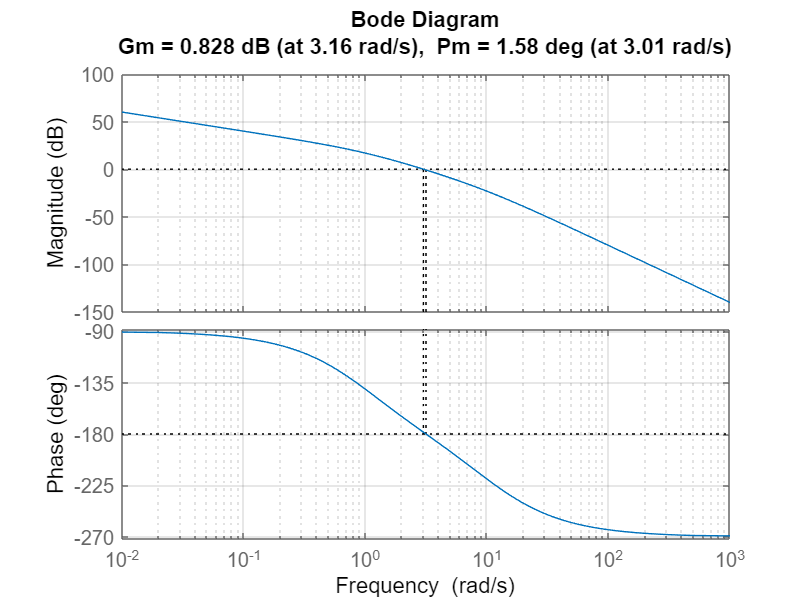

margin(G);
grid on

Design a lead compensator to increase the PM to 60deg at 5 rad/s:

w_max = 5;
theta_max = -120;
[~, phase] = bode(G, w_max);
Plead = theta_max-phase; % in degree
Clead = lead(Plead, w_max);

Include the lead compensator to open loop and adjust magnitute:

[mag, ~] = bode(Clead*G, w_max);
K = 1/mag*Clead;
L = K*G;

Test the designed lead compensator:

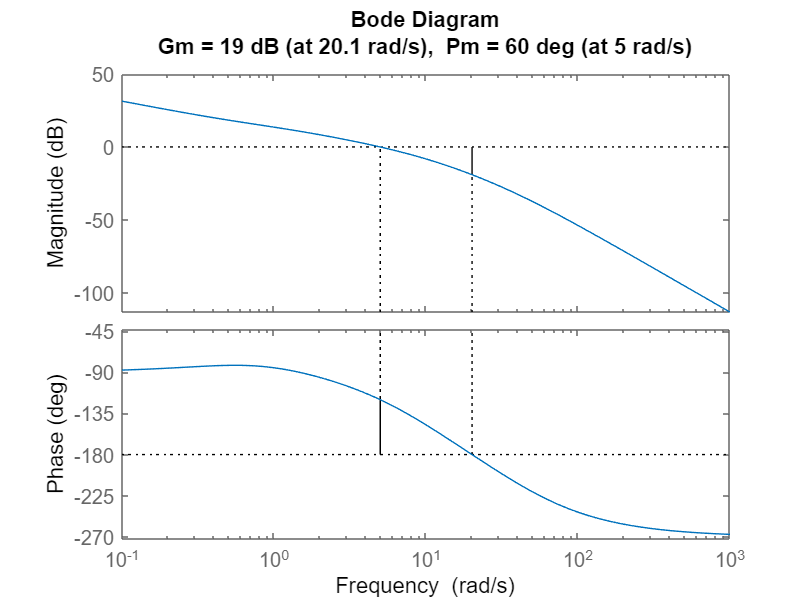

margin(L);

As shown in the margin plot, the designed lead compensator meets the specifications.

The step response of the closed loop system:

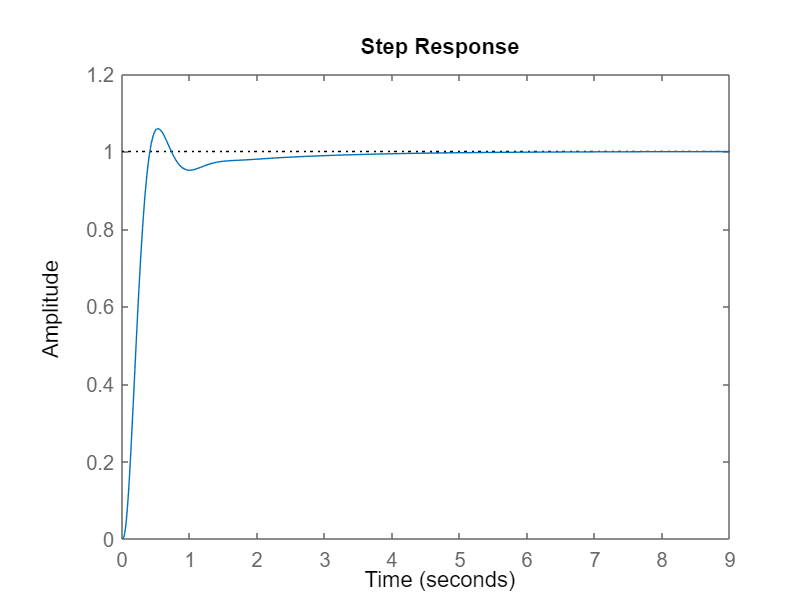

step(feedback(L,1));

(b)

According to the expected specifications, the system can be approximated with:

zeta = -log(.2)/sqrt(pi^2+(log(.2)^2))

zeta = 0.4559

w = 4/zeta/6

w = 1.4621

The dominant poles of the system should be placed at:

p_dom = roots([1 2*zeta*w w^2])

p_dom =   -0.6667 + 1.3013i
  -0.6667 - 1.3013i


Since the system is third-order, the non-dominant pole can be placed at five times further away from the dominant poles:

p_non = floor(5*real(p_dom(1,1)))

p_non = -4

Find a state space realization for the plant:

csys = canon(G,'companion'); 
A = csys.A;
B = csys.B;
C = csys.C;
D = csys.D;

The state feedback poles should be placed as previously calculated:

p_K = [p_dom;p_non];
K = place(A, B, p_K);

Since the observor should be faster than the controller, the error feedback poles can also be placed five times further away:

p_L = [p_non;p_non-1;p_non-2];
L = place(A',C', p_L)';

The full-state feedback system with an observer:


$$\begin{cases}
\dot x = (A-BK)x+BKe+B\bar Nr\\
\dot e = (A-LC)e
\end{cases}$$


Stack ${\left\lbrack x,e\right\rbrack }^T$as whole states, the closed loop system in state space:


$$\left[\matrix{\dot x \cr \dot e}\right] = \left[ \matrix{A-BK & BK \cr 0 & A-LC} \right]\left[\matrix{x \cr e}\right]+\left [ \matrix{B\bar N \cr 0}\right]r \\
y = \left[ \matrix{C & 0}\right] \left[\matrix{x \cr e}\right]
$$


Nbar = rscale(csys,K);
A_cl = [A-B*K, B*K; zeros(size(A)), A-L*C];
B_cl = [B*Nbar; zeros(size(B))];
C_cl = [C, zeros(size(C))];
sys_cl = ss(A_cl,B_cl,C_cl,0);

Simulate the unforced initial condition response (assume estimator has zero initial):

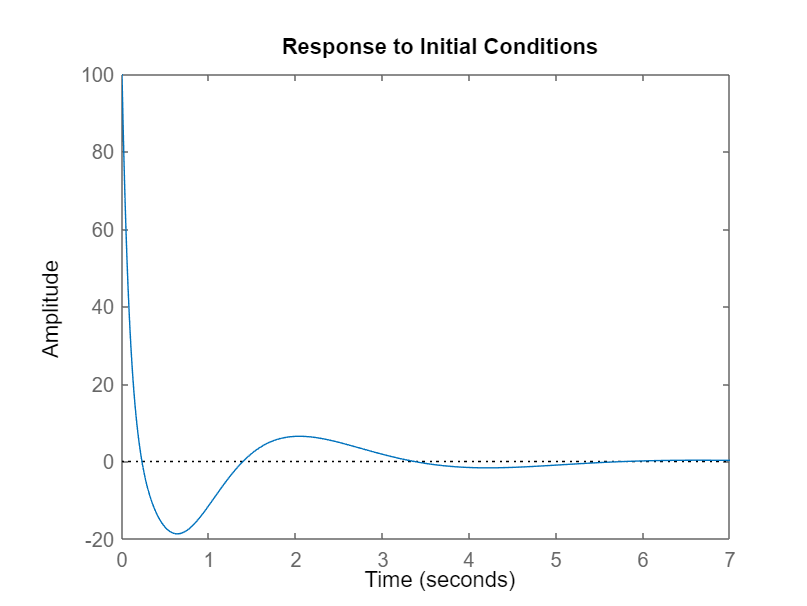

x0 = [0 0 1];
initial(sys_cl, [x0, x0])

The step response of the closed loop system is close to the required specifications:

SettlingTime = stepinfo(sys_cl).SettlingTime

SettlingTime = 5.9318

Overshoot = stepinfo(sys_cl).Overshoot

Overshoot = 18.4745

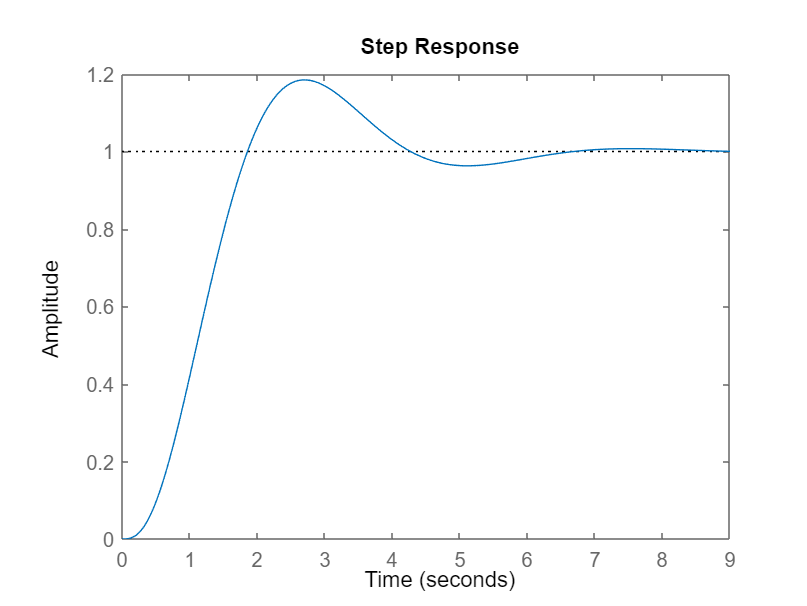

step(sys_cl);

Problem 3

(a)

clear; clc
load('HDD_freqresp.mat','HDD_freqresp')

The HDD plant has a delay due to sampling:

sys_hdd = HDD_freqresp;
s = tf('s');
Ts = 1/(50*1000);
sys_hdd_delay = sys_hdd*exp(-Ts/2*s);

Design a notch filter to eliminate the HF resonance for stability:

N = notch(25, 3000, 35000);

The desired crossover frequency is 1 kHz:

wc = 1000*2*pi;

Design PI controller with the same crossover frequency:

K_PI = (s+wc/10)/s;
[mag, ~] = bode(K_PI*N*sys_hdd_delay,wc);
K_PI = 1/mag*K_PI;

Design lead compensator to get PM at given crossover frequency:

[~,phase] = bode(K_PI*N*sys_hdd_delay,wc);
while phase>0
    phase = phase-360;
end
Plead = -135-phase;
Clead = lead(Plead,wc);

[mag,~] = bode(Clead*K_PI*N*sys_hdd_delay,wc);
K_lead = 1/mag*Clead;

Check if the goals are achieved:

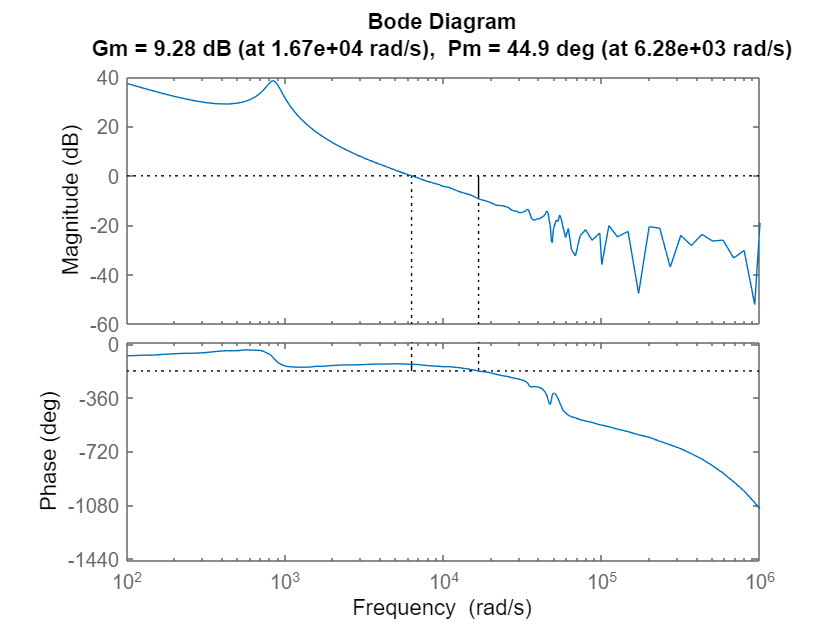

L = K_lead*K_PI*N*sys_hdd_delay;
margin(L);

(b)

The sensitivity function and the complementary sensitivity function:

S = 1/(1+L);
T = L/(1+L);

The magnitute peak of sensitivity function:

peak_S = getPeakGain(S)

peak_S = 1.8165

The magnitute peak of complementary sensitivity function:

peak_T = getPeakGain(T)

peak_T = 1.3727

(c) 

The 4th-order approximation of the colsed loop FRD system:

T_approx = fitfrd(T, 4);

The bode plot of approximated closed loop system with phase wrap;

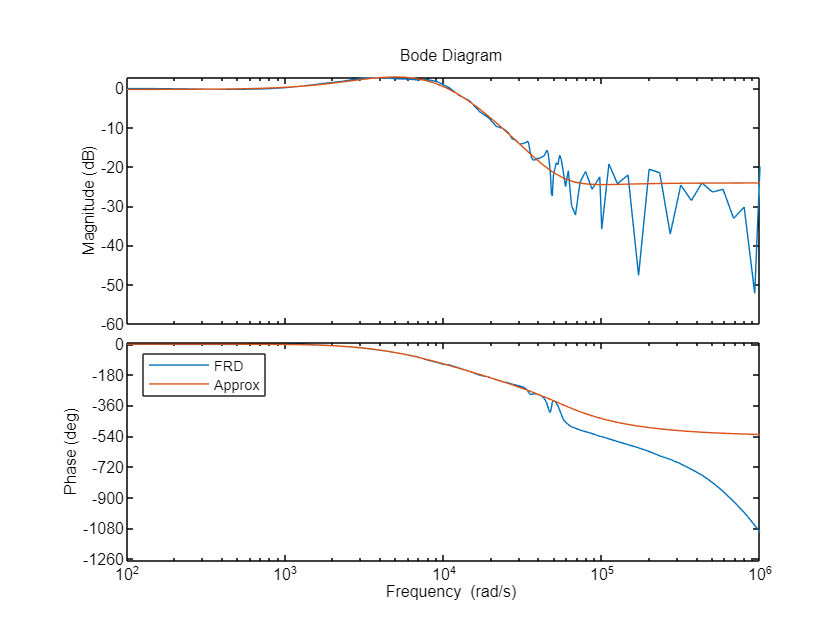

opts = bodeoptions;
opts.Phasematching = 'on';
opts.PhaseMatchingFreq = 0;
opts.PhaseMatchingValue = 0;
bodeplot(T, T_approx, opts);
legend({'FRD', 'Approx'},'Location','northwest');

The 4th-order approximation compared with other orders:

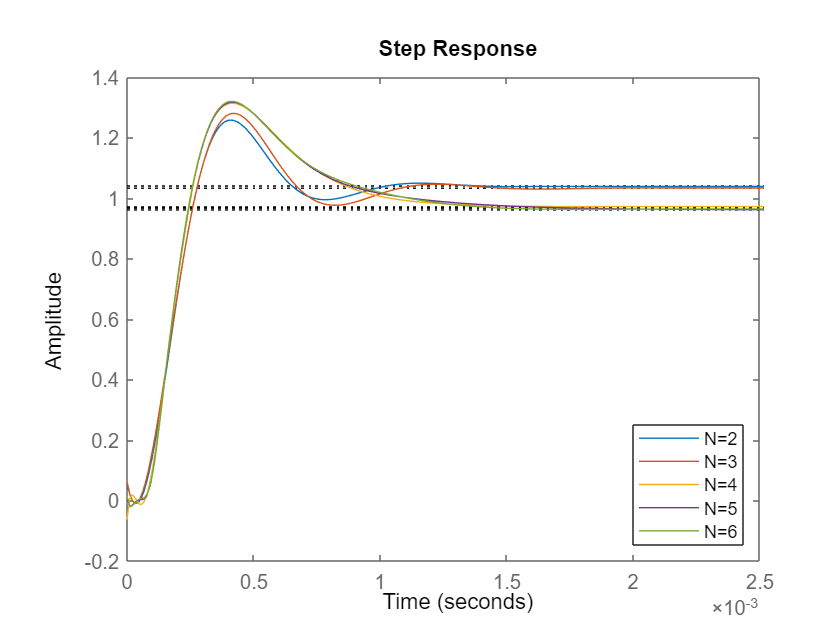

for n = 2:6
    T_approx_n = fitfrd(T, n);
    step(T_approx_n);
    hold on
end
hold off
legend('N=2','N=3','N=4','N=5','N=6','Location','southeast');

The step reponse of the approximated sytem:

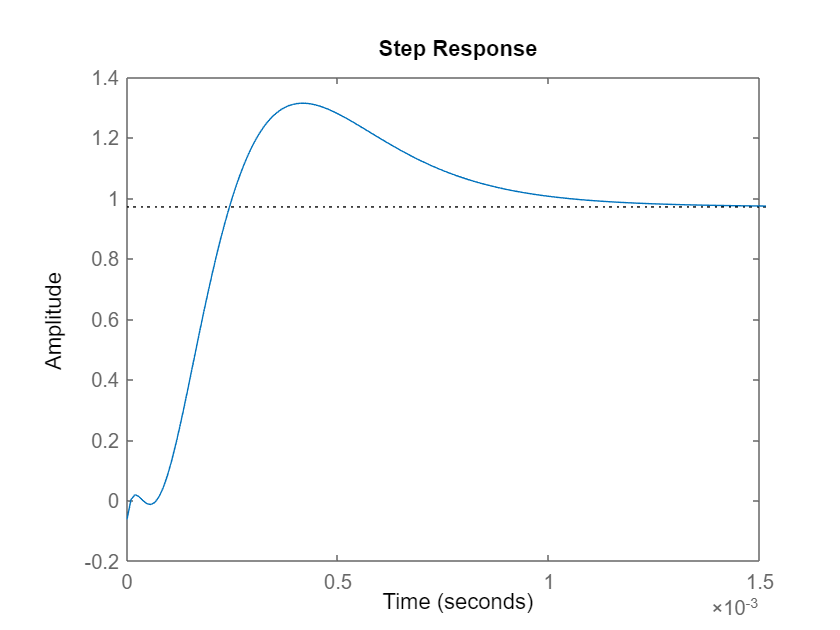

step(T_approx);